% % Loop through all dataset elements
% rms_array = zeros(1, 10);
% for i = 1:10
%     % Access each dataset element
%     element = data{i};  % Access the i-th dataset
% 
%     % Loop through all signals in each dataset (if there are multiple signals)
%     for j = 1:element.numElements
%         % Access the j-th signal in the i-th dataset
%         signal = element.getElement(3);
% 
%         % Extract time and data (assuming there are 11 data points)
%         time_values = signal.Values.Time;
%         data_values = signal.Values.Data;
% 
% 
% 
%         % Ensure there are exactly 11 data points
%         if length(data_values) == 11
%             fprintf('Dataset %d, Signal %d:\n', i, j);
%             disp('Time Values:');
%             disp(time_values);  % Display time values (11 points)
%             disp('Data Values:');
%             rms_value = sqrt(mean(data_values.^2));
%             disp(data_values);  % Display data values (11 points)
%             disp('rms_value:');
%             disp(rms_value);
%             rms_array(i) = rms_value;
%         else
% 
%             warning('Dataset %d, Signal %d does not have 11 data points.', i, j);
%         end
%     end
%     disp('rms_all_array:');
%     disp(rms_array);
%     save('rms_array.mat', 'rms_array');
% 
% end


% Access the element from the data array
element = data(1);  % In MATLAB, use parentheses for indexing

% Get the specific signal element from the structure
signal = element.getElement(3);

% Extract the data values from the signal
data_values = signal.Values.Data;

% Generate the index for the data values
index = 1:length(data_values);  % Use 1-based indexing in MATLAB
% Find valid (non-NaN) values
valid_indices = ~isnan(data_values);  % Use isnan() in MATLAB to find NaN values
valid_data = data_values(valid_indices);
valid_index = linspace(0,3.5,8)

valid_index =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000


valid_indices_list = valid_data(2:2:end);

% valid_index = 1:length(valid_data);
disp(length(valid_data));

    16



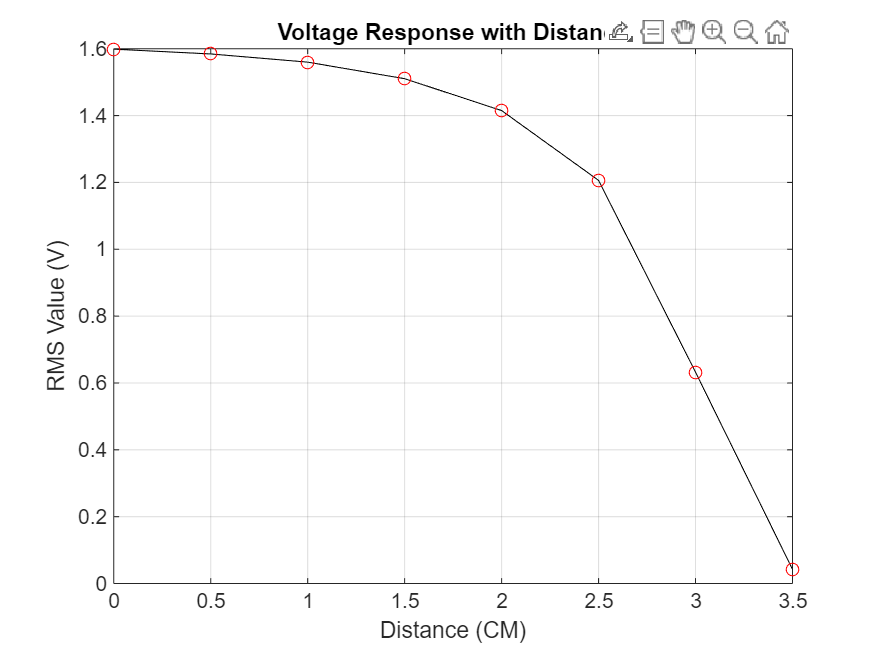


% Plot the valid data points
figure;
plot(valid_index, valid_indices_list, 'o', 'MarkerEdgeColor', 'r', 'LineStyle', '-', 'Color', 'k');
title('Voltage Response with Distance');
xlabel('Distance (CM)');
ylabel('RMS Value (V)');
grid on;


figure;

plot(valid_index, valid_data, 'o-', 'DisplayName', 'Original Data');  
hold on;  % Hold the current plot for adding the fit curve

fit_model = fit(valid_index', valid_data,'poly3','Normalize','on','Robust','Bisquare')

fit_model =      Linear model Poly3:
     fit_model(x) = p1*x^3 + p2*x^2 + p3*x + p4
       where x is normalized by mean 8.5 and std 4.761
     Coefficients (with 95% confidence bounds):
       p1 =    -0.09933  (-0.2087, 0.01009)
       p2 =     -0.3215  (-0.4131, -0.2299)
       p3 =     -0.3801  (-0.58, -0.1802)
       p4 =       1.418  (1.303, 1.533)

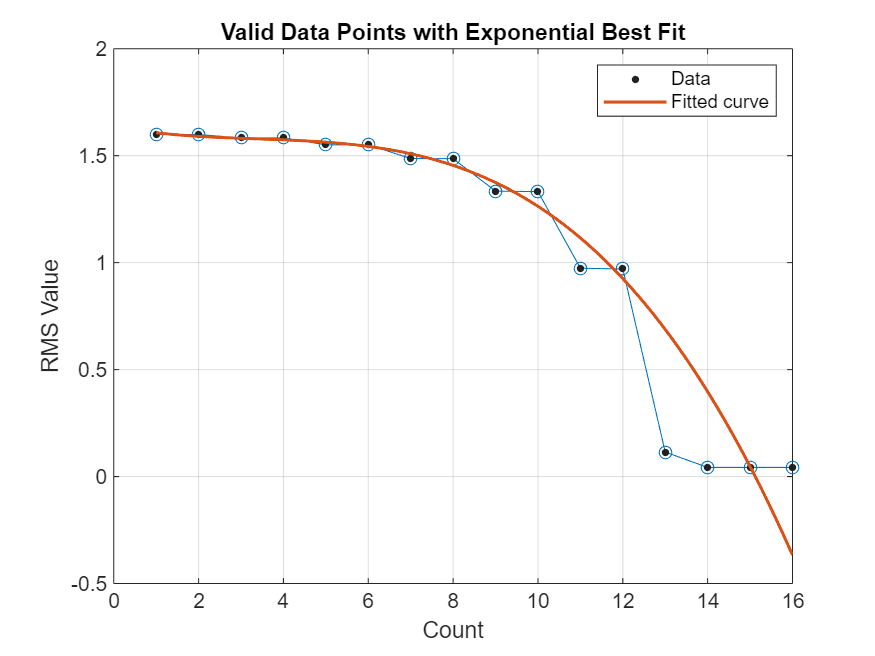

plot(fit_model,valid_index',valid_data);


title('Valid Data Points with Exponential Best Fit');
xlabel('Distance (CM)');
ylabel('RMS Value');

legend('show');

% Add grid for better visualization
grid on;

hold off;  % Release the plot hold

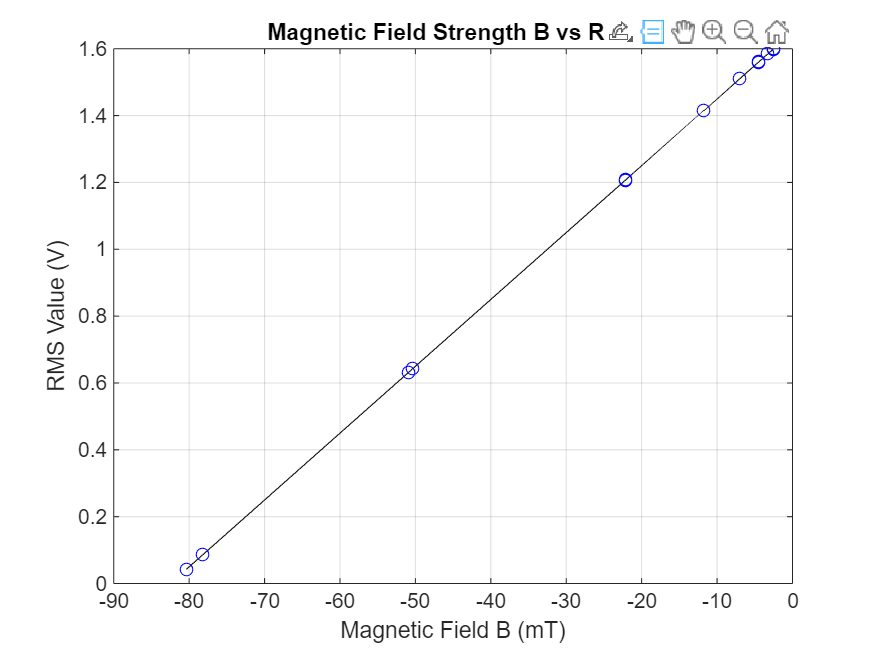

V_Q = 1.65;  
Sensitivity_25C = 0.02;  

element = data(1);  

signal = element.getElement(3);

data_values = signal.Values.Data;

index = 1:length(data_values);  

valid_indices = ~isnan(data_values);  
valid_data = data_values(valid_indices);

B = (valid_data - V_Q) / Sensitivity_25C;

figure;
plot(B, valid_data, 'o', 'MarkerEdgeColor', 'b', 'LineStyle', '-', 'Color', 'k');
title('Magnetic Field Strength B vs RMS');
xlabel('Magnetic Field B (mT)');
ylabel('RMS Value (V)');  
grid on;

% Access Noshoeld
element = data(1);  

signal = element.getElement(3);

data_values = signal.Values.Data;

index = 1:length(data_values);  
valid_indices = ~isnan(data_values); 
valid_data = data_values(valid_indices);
valid_index = 1:length(valid_data);
valid_index = linspace(0,3.5,8)

valid_index =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000


valid_indices_list = valid_data(2:2:end);

% valid_index = 1:length(valid_data);
disp(length(valid_data));

    16



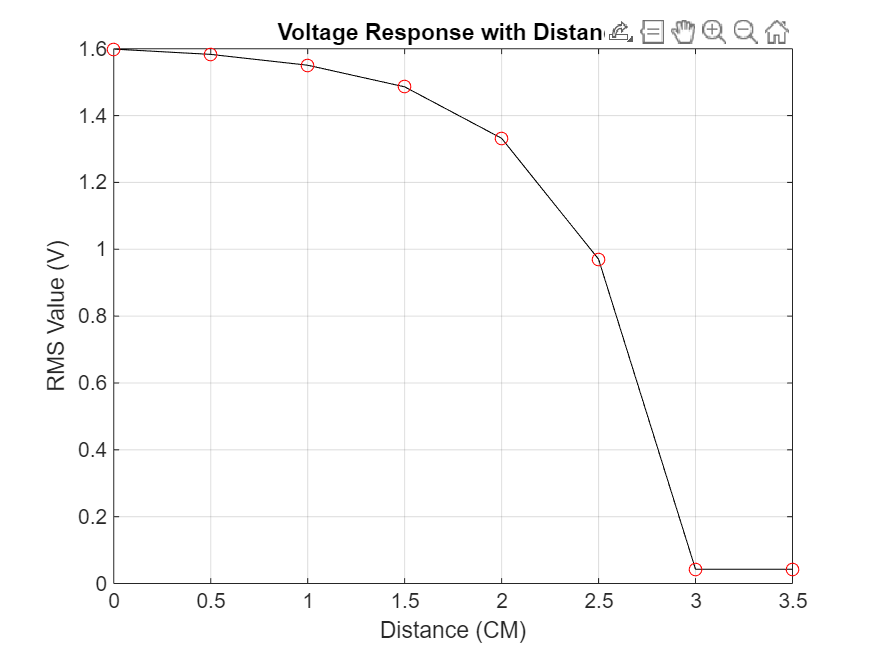


% Plot the valid data points
figure;
plot(valid_index, valid_indices_list, 'o', 'MarkerEdgeColor', 'r', 'LineStyle', '-', 'Color', 'k');
title('Voltage Response with Distance');
xlabel('Distance (CM)');
ylabel('RMS Value (V)');
grid on;

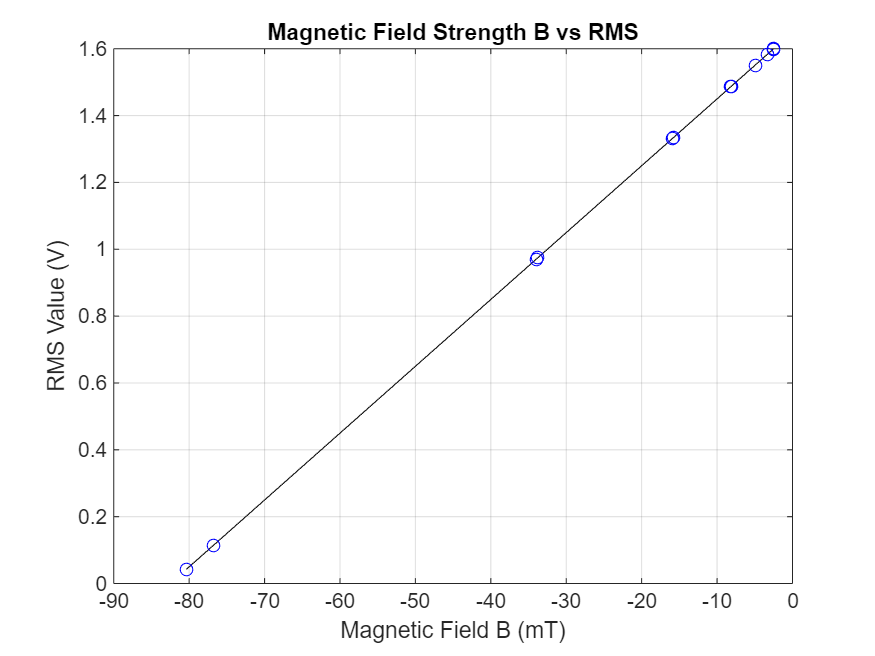

V_Q = 1.65;  
Sensitivity_25C = 0.02;  

element = data(1);  

signal = element.getElement(3);

data_values = signal.Values.Data;

index = 1:length(data_values);  

valid_indices = ~isnan(data_values);  
valid_data = data_values(valid_indices);

B = (valid_data - V_Q) / Sensitivity_25C;

figure;
plot(B, valid_data, 'o', 'MarkerEdgeColor', 'b', 'LineStyle', '-', 'Color', 'k');
title('Magnetic Field Strength B vs RMS');
xlabel('Magnetic Field B (mT)');
ylabel('RMS Value (V)');  
grid on;